# Compute the Fundamental Natural Frequency (resonance) of a Plate

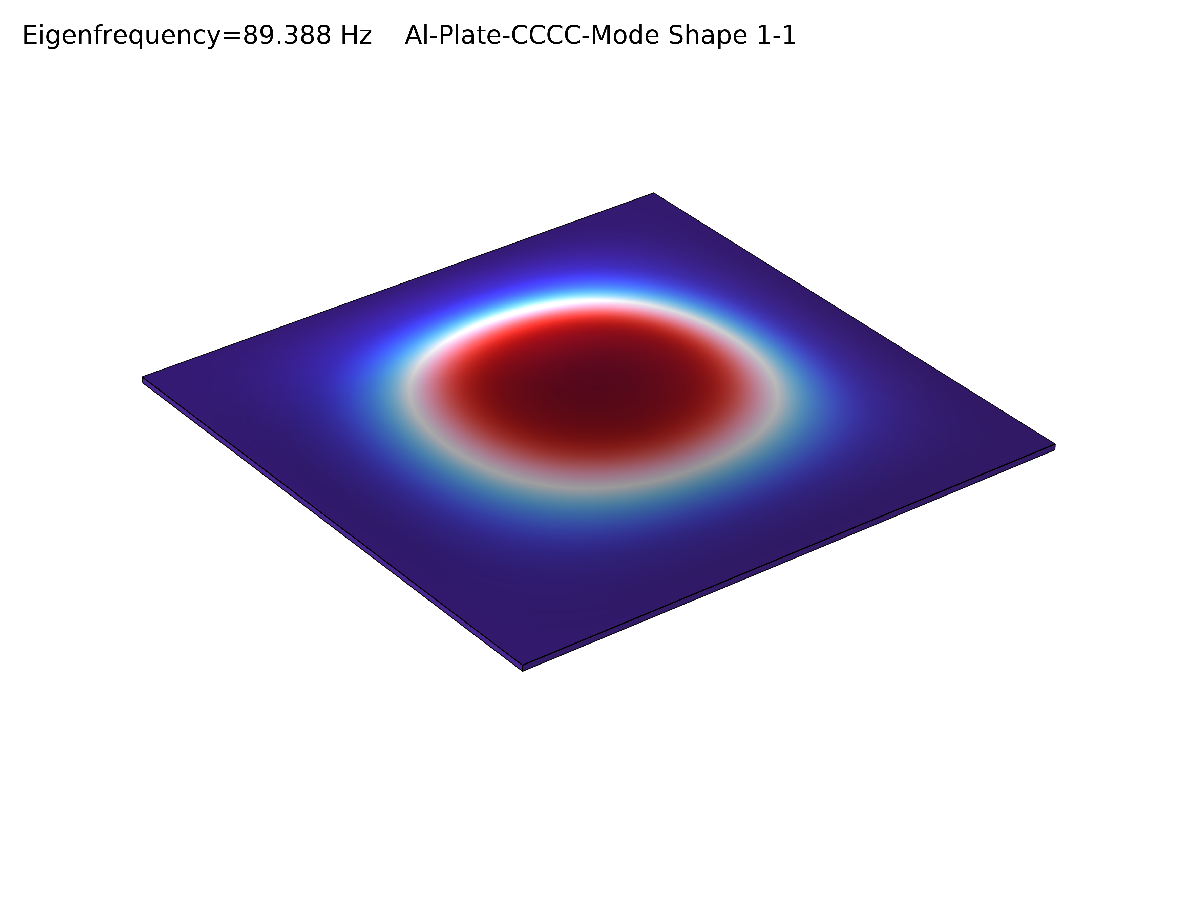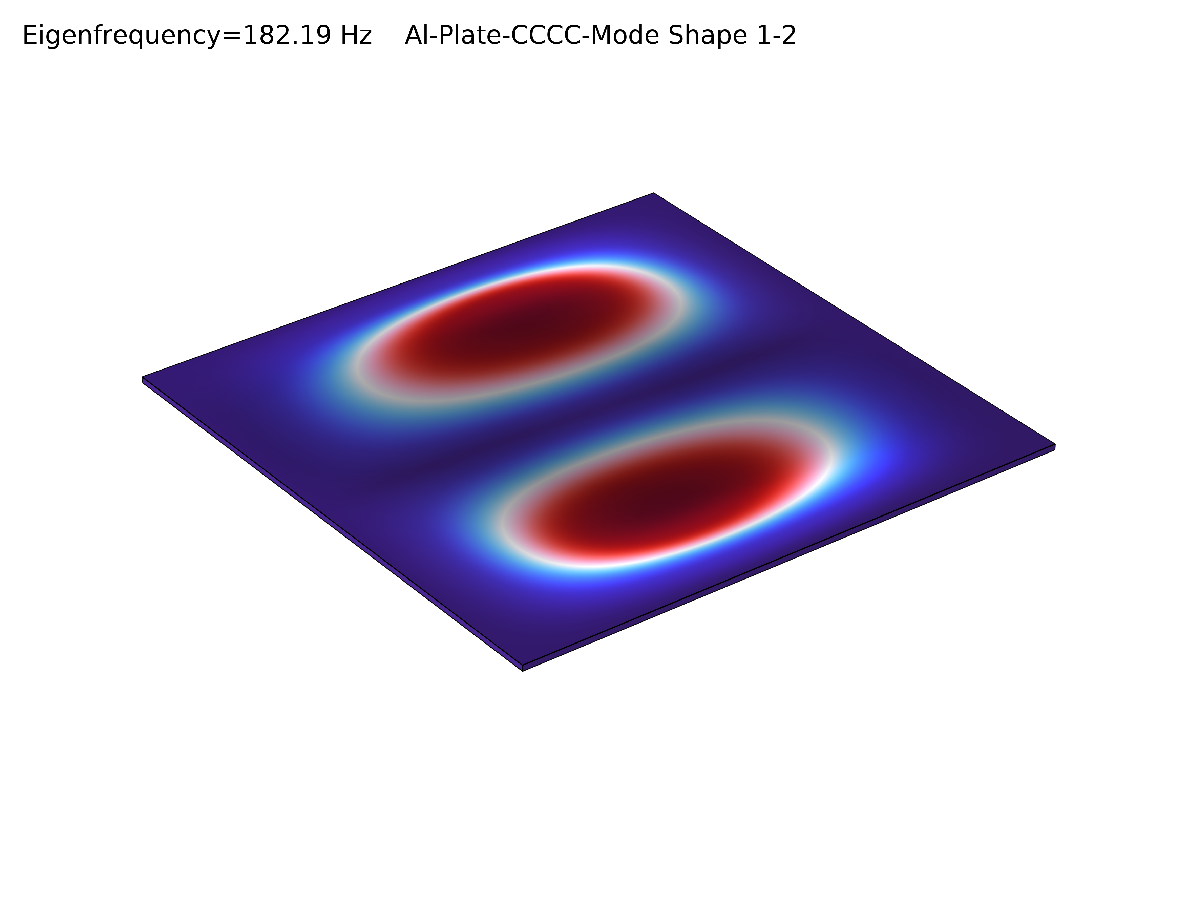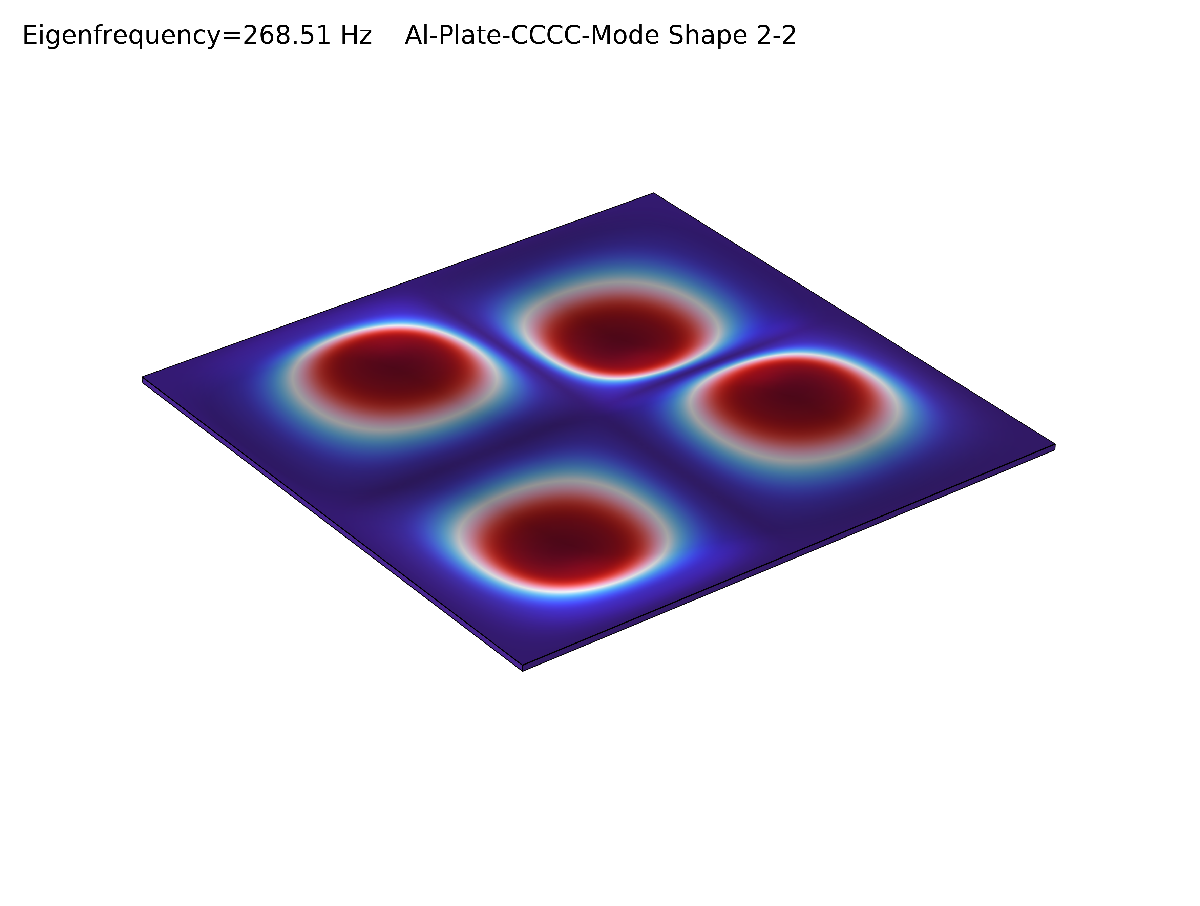

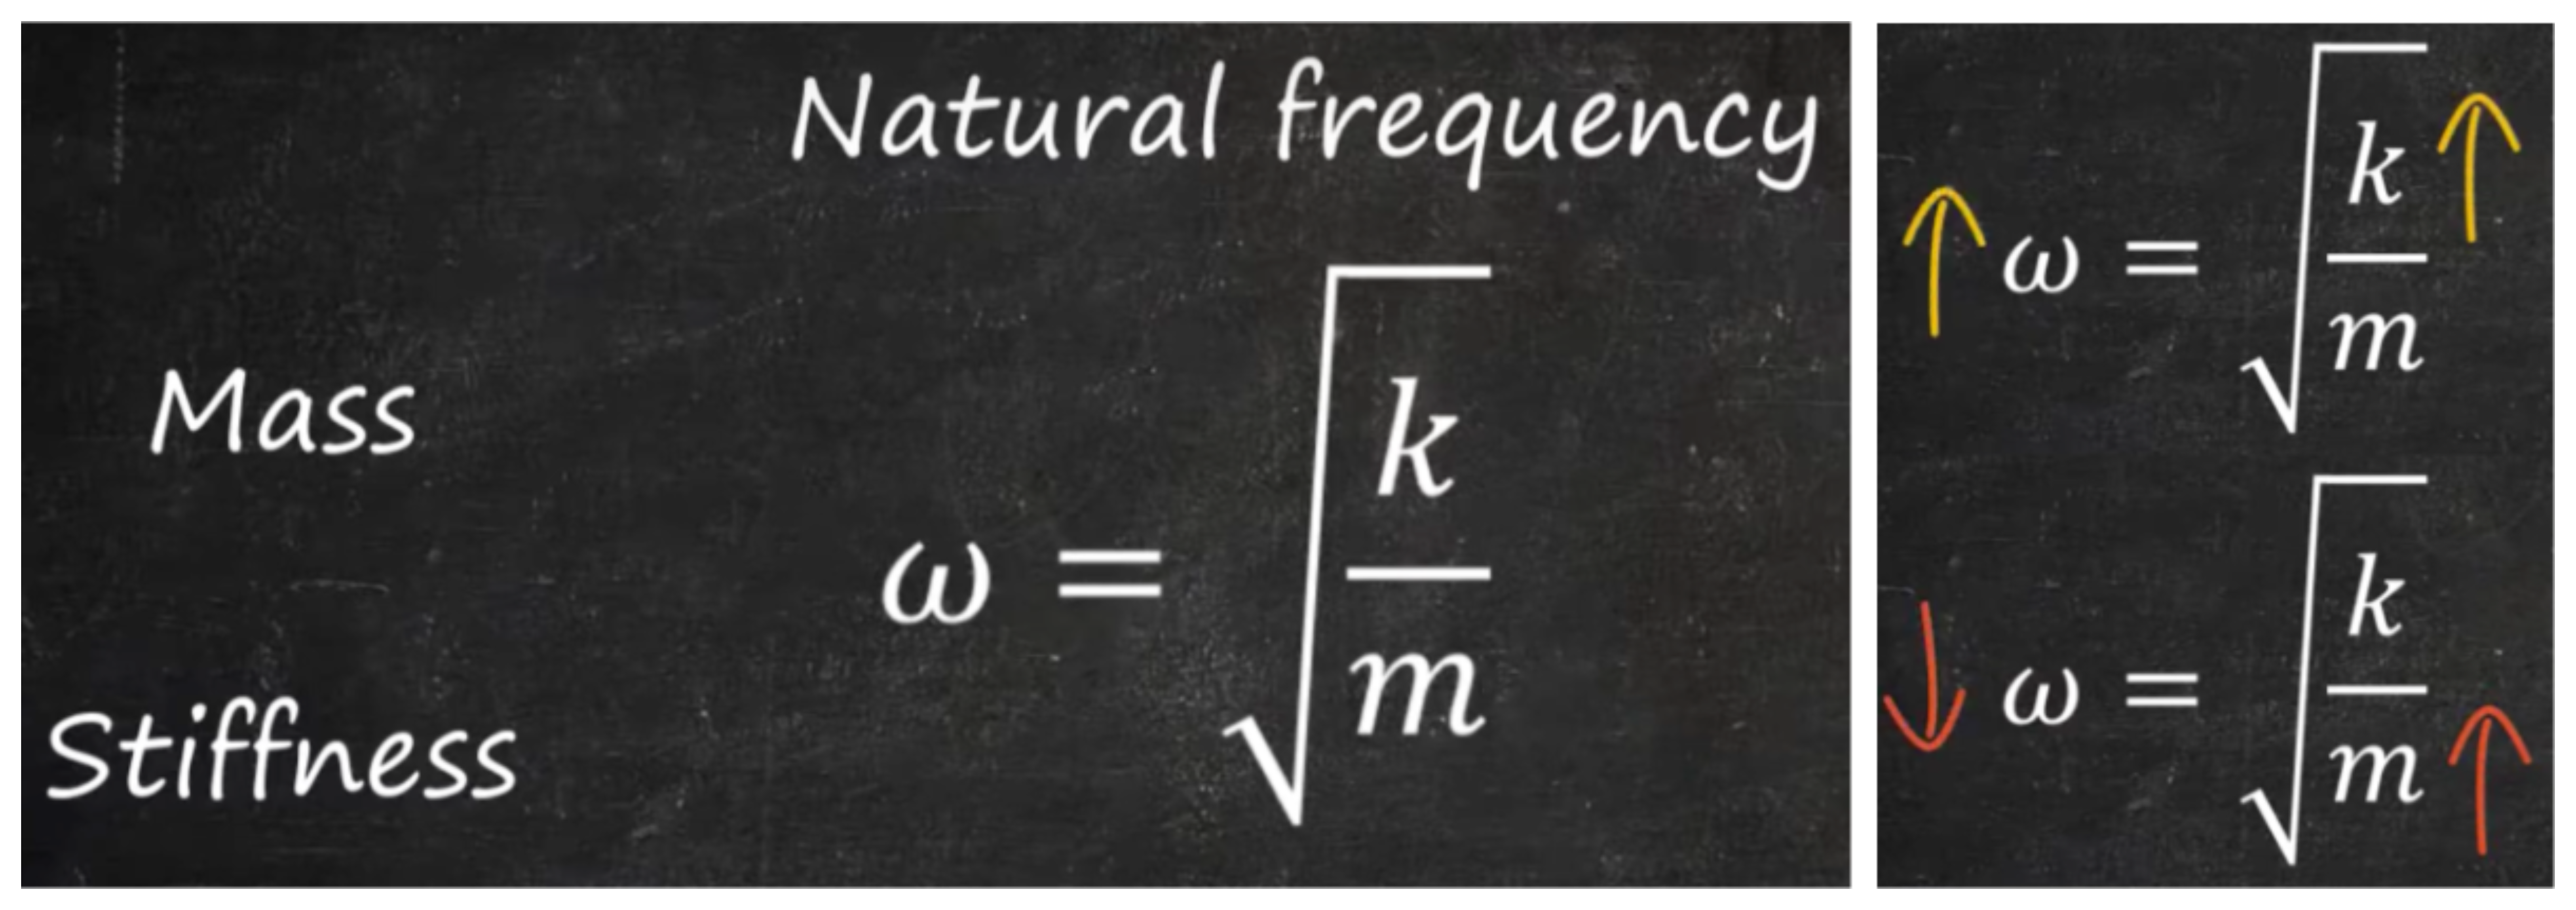

## Matlab Startup File

This m-File code prepare the enviroment to provide access to auxilliary files and sub-folders.

clear; clc; close all;
format short eng                              
[ProjectFolder,AuxFcn_GS] = AuxFcn_Matlab_Startup_File_001; % Project Startup Folder & Graphical Settings

# Steel Plate - Fundamental Natural Frequency Analysis (S-S-S-C)

### 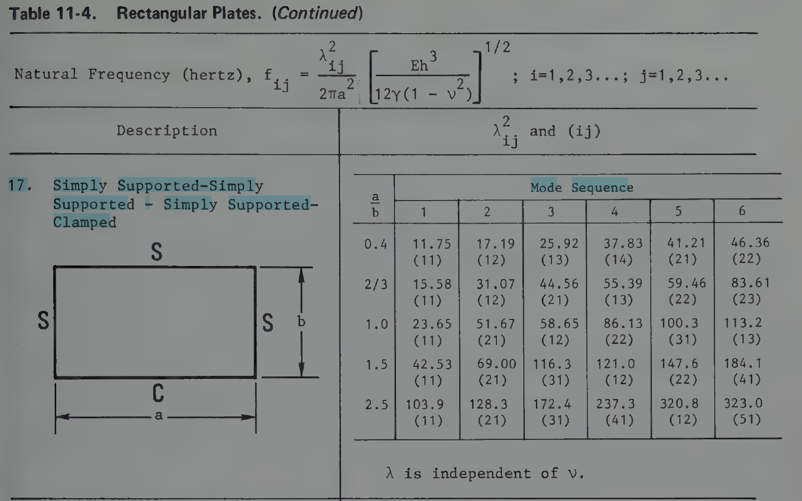

## Steel Plate - Effect of Aspect Ratio on Fundamental Natural Frequency (S-S-S-S)

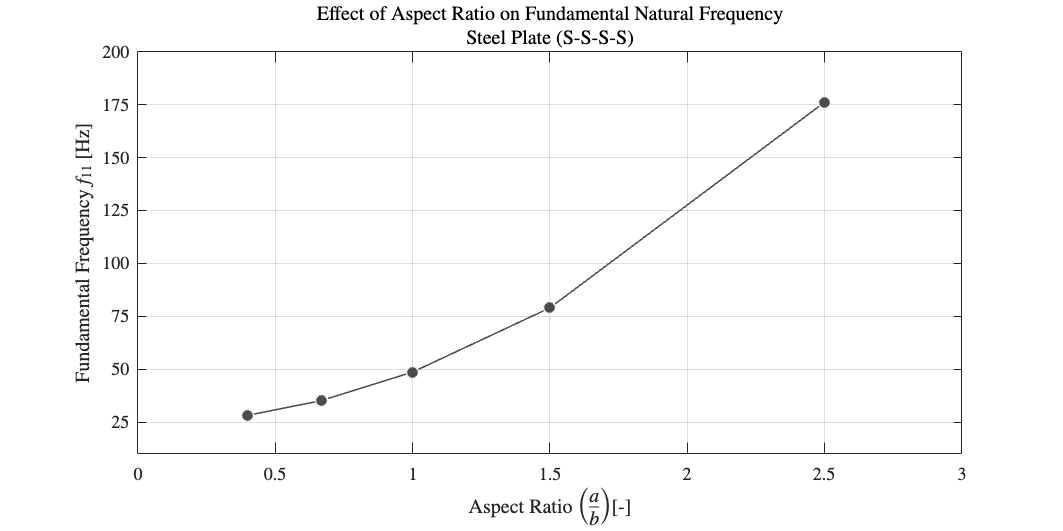

% Given Data
a = 1;        % Plate length in meters (constant)
h = 0.010;        % Plate thickness in meters (10 mm)

% Material Properties for Steel
E = 205e9;        % Young's modulus in Pascals (N/m^2)
nu = 0.3;         % Poisson's ratio
rho = 7850;       % Density in kg/m^3

% Compute mass per unit area
gamma = h * rho;  

% Aspect ratios from the book
aspect_ratios = [0.4, 2/3, 1, 1.5, 2.5];

% Compute corresponding "b" values to match aspect ratios
b_values = a ./ aspect_ratios;  

% Corresponding lambda_11^2 values from the book’s table for S-S-S-S
lambda_squared = [11.45, 14.26, 19.74, 32.08, 71.56];  % Taken from the book

% Define the handle function exactly as you originally wrote it (with lambda^2)
f_ij = @(lambda_ij) (lambda_ij / (2 * pi * a^2)) * sqrt((E * h^3) / (12 * gamma * (1 - nu^2)));

% Compute fundamental frequencies using lambda_11^2
f_values = f_ij(lambda_squared);

% Plot results
figure;
x0=10;
y0=10;
width=25;
height=12.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height])

plot(aspect_ratios, f_values,'-o', 'LineWidth', 1, ...
    'MarkerSize', 8, 'MarkerFaceColor', AuxFcn_GS.grey_x, ...
    'MarkerEdgeColor', AuxFcn_GS.grey_light, 'Color', AuxFcn_GS.grey_x);
AuxFcn_Figure_Settings('Aspect Ratio $\left(\frac{a}{b}\right)$[-]','Fundamental Frequency $f_{11}$ [Hz]',''...
    ,{'Effect of Aspect Ratio on Fundamental Natural Frequency','Steel Plate (S-S-S-S)'},12)
ylim([10 200])
yticks(0:25:200)
xlim([0 3])
grid on;

% Display results in a table
disp('Aspect Ratio (a/b) vs Fundamental Frequency (Hz):');

Aspect Ratio (a/b) vs Fundamental Frequency (Hz):


disp(table(aspect_ratios', b_values', f_values', 'VariableNames', {'Aspect_Ratio', 'b_Value_m', 'f11_Hz'}));

    Aspect_Ratio    b_Value_m    f11_Hz
    ____________    _________    ______

          0.4            2.5     28.181
      0.66667            1.5     35.097
            1              1     48.585
          1.5        0.66667     78.956
          2.5            0.4     176.13



## Steel Plate - Effect of Plate Thickness on Fundamental Frequency (S-S-S-S)

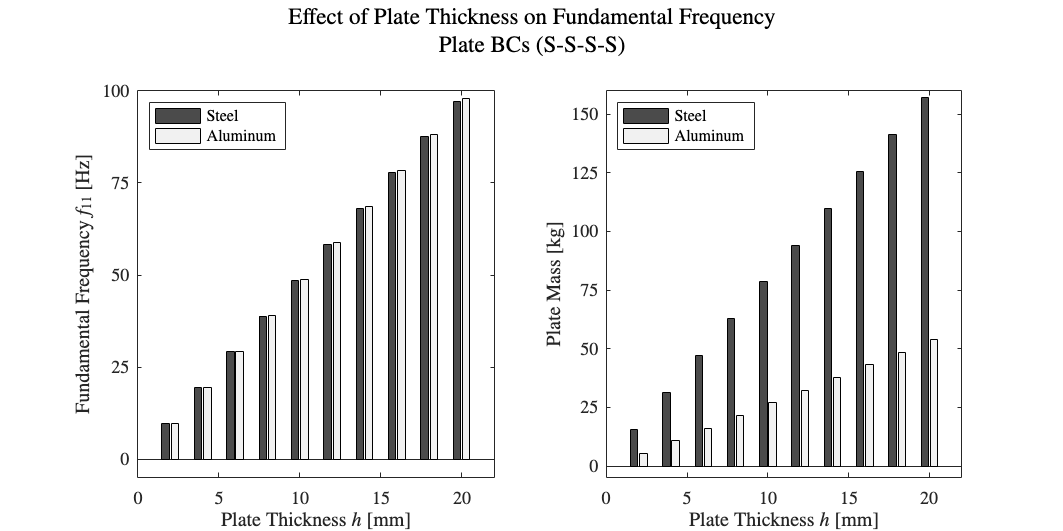

% Given Data
a = 1;        % Plate length in meters (constant)
b = 1;        % Plate width in meters (constant) (Aspect Ratio = 1)

% Material Properties for Steel
E_S = 205e9;        % Young's modulus in Pascals (N/m^2)
nu_S = 0.3;         % Poisson's ratio
rho_S = 7850;       % Density in kg/m^3

% Material Properties for Aluminum
E_Al = 70e9;     % Young's modulus in Pascals (N/m^2)
nu_Al = 0.33;    % Poisson's ratio
rho_Al = 2700;   % Density in kg/m^3

% Thickness values (2 mm to 20 mm in increments of 2 mm)
thickness_values = (2:2:20) * 1e-3; % Convert mm to meters

% Mass
mass_S = a * b * thickness_values * rho_S;
mass_Al = a * b * thickness_values * rho_Al;

% Lambda-squared value for fundamental mode (1,1) from the book’s table
lambda_ij = 19.74; % Aspect Ratio 1.0 (S-S-S-S)

% Compute mass per unit area
gamma_S = thickness_values.*rho_S;
gamma_Al = thickness_values.*rho_Al;
% Define the frequency calculation function
f_ij = @(E,h,gamma,nu) (lambda_ij / (2 * pi * a^2)) * sqrt((E * h.^3) ./ (12 .* gamma .* (1 - nu^2)));

% Compute frequencies for each thickness
f_S_values = f_ij(E_S,thickness_values,gamma_S,nu_S);
f_Al_values = f_ij(E_Al,thickness_values,gamma_Al,nu_Al);

% Plot frequency vs thickness
figure;
x0=10;
y0=10;
width=25;
height=12.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height])

subplot(1,2,1)
barPlot = bar(thickness_values * 1e3,[f_S_values;f_Al_values]);
AuxFcn_Figure_Settings('Plate Thickness $h$ [mm]','Fundamental Frequency $f_{11}$ [Hz]',''...
    ,{''},12)
barPlot(1).FaceColor = AuxFcn_GS.grey_x;
barPlot(2).FaceColor = AuxFcn_GS.grey_light;
ylim([-5 100])
yticks(0:25:100)
xlim([0 22])
legend('Steel', 'Aluminum', 'Location','northwest')
grid off;
% axis tight
hold off
% Plot frequency vs mass
% figure
subplot(1,2,2)
barPlot = bar(thickness_values * 1e3,[mass_S;mass_Al]);
AuxFcn_Figure_Settings('Plate Thickness $h$ [mm]','Plate Mass [kg]',''...
    ,{''},12)
barPlot(1).FaceColor = AuxFcn_GS.grey_x;
barPlot(2).FaceColor = AuxFcn_GS.grey_light;
ylim([-5 160])
yticks(0:25:160)
xlim([0 22])
legend('Steel', 'Aluminum', 'Location','northwest')
grid off;
% axis tight
hold off
sgtitle({'Effect of Plate Thickness on Fundamental Frequency','Plate BCs (S-S-S-S)'}) 

% Display results in a table
disp('Plate Thickness (mm) vs Fundamental Frequency (Hz):');

Plate Thickness (mm) vs Fundamental Frequency (Hz):


disp(table(thickness_values' * 1e3,  f_S_values', 'VariableNames', {'Thickness_mm', 'f11_Hz'}));

    Thickness_mm    f11_Hz
    ____________    ______

          2         9.7169
          4         19.434
          6         29.151
          8         38.868
         10         48.585
         12         58.301
         14         68.018
         16         77.735
         18         87.452
         20         97.169



## Material Comparison - Fundamental Natural Frequency Analysis (S-S-S-S)

% Given Data (Plate Geometry - Aspect Ratio 1)
a = 1;        % Plate length in meters
b = 1;        % Plate width in meters
h_values = [0.010, 0.020];  % Thicknesses to analyze (10 mm & 20 mm for PMMA)

% Material Properties
materials = {'Steel', 'Aluminum', 'PMMA 10mm', 'PMMA 20mm'};
E_values = [205e9, 70e9, 2.8e9, 2.8e9];  % Young's modulus (Pa)
nu_values = [0.3, 0.33, 0.35, 0.35];  % Poisson's ratio
rho_values = [7850, 2700, 1190, 1190];  % Density (kg/m³)
thickness_values = [h_values(1), h_values(1), h_values(1), h_values(2)];  % Thickness for each case

% Lambda-squared value for fundamental mode (1,1) from the book’s table
lambda_ij = 19.74; % Aspect Ratio 1.0 (S-S-S-S)

% Define the corrected frequency calculation function
f_ij = @(E, nu, rho, h) (lambda_ij / (2 * pi * a^2)) .* sqrt((E * h.^3) ./ (12 .* (rho .* h) .* (1 - nu.^2)));

% Compute f_values for each material
f_values = zeros(size(materials));

for i = 1:length(materials)
    f_values(i) = f_ij(E_values(i), nu_values(i), rho_values(i), thickness_values(i));
end

% Compute expected Steel-to-Aluminum ratio
freq_ratio = sqrt((205e9 * (1 - 0.33^2)) / (70e9 * (1 - 0.3^2)) * (2700 / 7850));

% Direct manual calculations for comparison
f_Alu = f_ij(70e9, 0.33, 2700, 0.010);
f_Steel = f_ij(205e9, 0.3, 7850, 0.010);

% Compute actual frequency ratio
freq_ratio_check = f_Steel / f_Alu

freq_ratio_check =    993.1560e-003



% Display the expected vs computed ratio
fprintf('Computed f_Steel / f_Aluminum = %.4f\n', freq_ratio);

Computed f_Steel / f_Aluminum = 0.9932


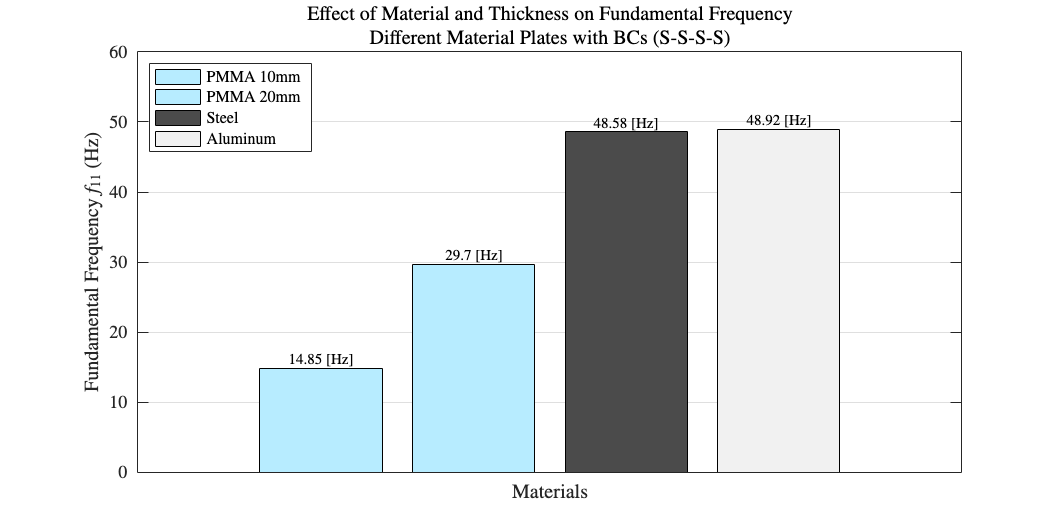


% Sort frequencies in ascending order
[sorted_f_values, sort_idx] = sort(f_values, 'ascend');  % Sorting frequencies numerically
sorted_materials = materials(sort_idx);  % Reordering materials
sorted_thickness = thickness_values(sort_idx);  % Reordering thickness

% Define custom colors for each material
bar_colors = [AuxFcn_GS.grey_x;  % (Steel)
              AuxFcn_GS.grey_light;  % (Aluminum)
              AuxFcn_GS.skyblue_light;  % (PMMA 10mm)
              AuxFcn_GS.skyblue_light]; % (PMMA 20mm)

% Reorder colors to match the sorted data
sorted_colors = bar_colors(sort_idx, :);

% Plot sorted results with different colors
figure;
x0=10;
y0=10;
width=25;
height=12.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height])

b = bar(sorted_f_values, 'FaceColor', 'flat'); % Set FaceColor to 'flat' for coloring
hold on;

% Apply colors to each bar
for i = 1:length(sorted_materials)
    b.CData(i, :) = sorted_colors(i, :); % Assign colors to each bar
end

% Add text labels on top of bars
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = append(string(round(sorted_f_values, 2)), ' [Hz]'); % Round frequency values
text(xtips, ytips, labels, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 10);

% Set x-axis label as "Materials" instead of listing each material
xticks([]); % Remove individual material names from x-axis

AuxFcn_Figure_Settings('Materials','Fundamental Frequency $f_{11}$ (Hz)',''...
    ,{'Effect of Material and Thickness on Fundamental Frequency','Different Material Plates with BCs (S-S-S-S)'},12)

% Add legend manually using "dummy" bars
hold on;
legend_handles = gobjects(length(materials),1);  % Create empty objects for legend
for i = 1:length(sorted_materials)
    legend_handles(i) = bar(nan, nan, 'FaceColor', sorted_colors(i, :)); % Create dummy bars for legend
end
legend(legend_handles, sorted_materials, 'Location', 'northwest');
ylim([0 60])
hold off;

% Display results in a table (sorted)
disp('Sorted Material vs Fundamental Frequency (Hz):');

Sorted Material vs Fundamental Frequency (Hz):


disp(table(sorted_materials', sorted_thickness', sorted_f_values', 'VariableNames', {'Material', 'Thickness_m', 'f11_Hz'}));

      Material       Thickness_m    f11_Hz
    _____________    ___________    ______

    {'PMMA 10mm'}       0.01        14.851
    {'PMMA 20mm'}       0.02        29.702
    {'Steel'    }       0.01        48.585
    {'Aluminum' }       0.01        48.919



## Plate Size Comparison - Fundamental Natural Frequency Analysis (S-S-S-S)

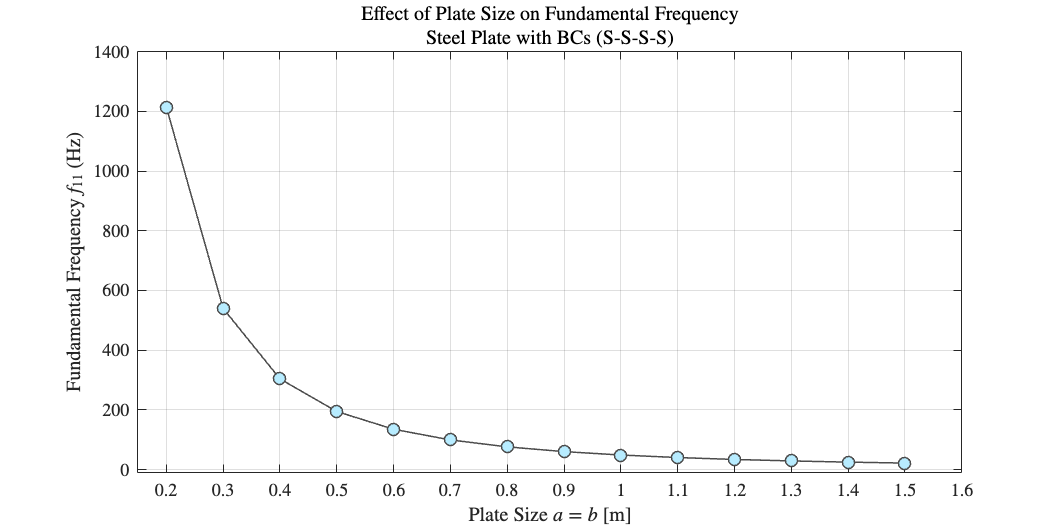

% Given Data
h = 0.010;        % Plate thickness in meters (10 mm)
E = 205e9;        % Young's modulus for Steel (Pa)
nu = 0.3;         % Poisson's ratio
rho = 7850;       % Density (kg/m³)

% Lambda-squared value for fundamental mode (1,1) from the book’s table
lambda_ij = 19.74; % Aspect Ratio 1.0 (S-S-S-S)

% Plate sizes (from 250 mm to 1500 mm in steps of 250 mm)
plate_sizes = (200:100:1500) * 1e-3;  % Convert mm to meters

% Define frequency calculation function
f_ij = @(a) (lambda_ij / (2 * pi * a^2)) .* sqrt((E * h^3) ./ (12 .* (rho .* h) .* (1 - nu^2)));

% Compute fundamental frequencies for each plate size
frequencies = arrayfun(f_ij, plate_sizes);

% Plot frequency vs plate size
figure;
x0=10;
y0=10;
width=25;
height=12.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height])
plot(plate_sizes, frequencies,'-o', 'LineWidth', 1, ...
    'MarkerSize', 8, 'MarkerFaceColor', AuxFcn_GS.skyblue_light, ...
    'MarkerEdgeColor', AuxFcn_GS.grey_x, 'Color', AuxFcn_GS.grey_x);

AuxFcn_Figure_Settings('Plate Size $a = b$ [m]','Fundamental Frequency $f_{11}$ (Hz)',''...
    ,{'Effect of Plate Size on Fundamental Frequency','Steel Plate with BCs (S-S-S-S)'},12)
% grid on;

yticks(0:200:1400)
ylim([-10 1400])
xticks(0.200:0.100:1.600)
xlim([0.150 1.600])

% Display results in a table
disp('Plate Size [m] vs Fundamental Frequency (Hz):');

Plate Size [m] vs Fundamental Frequency (Hz):


disp(table(plate_sizes', frequencies', 'VariableNames', {'Plate_Size_m', 'f11_Hz'}));

    Plate_Size_m    f11_Hz
    ____________    ______

        0.2         1214.6
        0.3         539.83
        0.4         303.65
        0.5         194.34
        0.6         134.96
        0.7         99.152
        0.8         75.913
        0.9         59.981
          1         48.585
        1.1         40.153
        1.2         33.739
        1.3         28.748
        1.4         24.788
        1.5         21.593



## Boundary Condition Comparison - Fundamental Natural Frequency Analysis

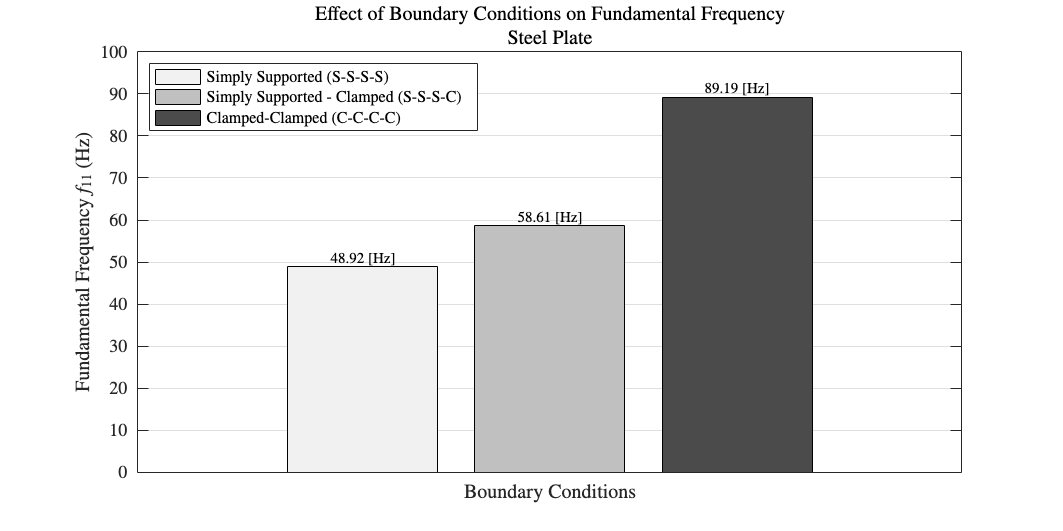

% Given Data
a = 1;        % Plate length in meters
b = 1;        % Plate width in meters
h = 0.010;     % Plate thickness in meters (10 mm)

% Material Properties for Aluminum
E = 70e9;     % Young's modulus in Pascals (N/m^2)
nu = 0.33;    % Poisson's ratio
rho = 2700;   % Density in kg/m^3

% Compute mass per unit area
gamma = rho * h;

% Boundary Conditions to Compare
BC_types = {'Simply Supported (S-S-S-S)', 'Simply Supported - Clamped (S-S-S-C)', 'Clamped-Clamped (C-C-C-C)'};

% Lambda-squared values for fundamental mode (1,1) from the book’s table
lambda_ij_values = [19.74, 23.65, 35.99];  % Corresponding to BCs

% Define the frequency calculation function
f_ij = @(lambda_ij) (lambda_ij / (2 * pi * a^2)) * sqrt((E * h^3) / (12 * gamma * (1 - nu^2)));

% Compute fundamental frequencies for each boundary condition
f_values = arrayfun(f_ij, lambda_ij_values);

% Define custom colors for boundary conditions
bar_colors = [AuxFcn_GS.grey_light;  %  (S-S-S-S)
              AuxFcn_GS.grey;  %  (S-S-S-C)
              AuxFcn_GS.grey_x]; %  (C-C-C-C)

% Plot results with different colors
figure;
x0=10;
y0=10;
width=25;
height=12.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height])
bar_Plot = bar(f_values, 'FaceColor', 'flat');
hold on;

% Apply colors to each bar
for i = 1:length(BC_types)
    bar_Plot.CData(i, :) = bar_colors(i, :);
end

% Add text labels on top of bars
xtips = bar_Plot.XEndPoints;
ytips = bar_Plot.YEndPoints;
labels = append(string(round(f_values, 2)), ' [Hz]'); % Round frequency values
text(xtips, ytips, labels, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 10);

% Set x-axis label as "Boundary Conditions"
xticklabels(BC_types);
% xtickangle(15); % Rotate labels for readability
ylim([0 100])
% % Title
% title('Effect of Boundary Conditions on Fundamental Frequency');
% 
% % Add legend
% legend(BC_types, 'Location', 'northwest');
% Set x-axis label as "Materials" instead of listing each material
xticks([]); % Remove individual material names from x-axis

AuxFcn_Figure_Settings('Boundary Conditions','Fundamental Frequency $f_{11}$ (Hz)',''...
    ,{'Effect of Boundary Conditions on Fundamental Frequency','Steel Plate'},12)

% Add legend manually using "dummy" bars
hold on;
legend_handles = gobjects(length(BC_types),1);  % Create empty objects for legend
for i = 1:length(BC_types)
    legend_handles(i) = bar(nan, nan, 'FaceColor', bar_colors(i, :)); % Create dummy bars for legend
end
legend(legend_handles, BC_types, 'Location', 'northwest');

hold off;



% Display results in a table
disp('Boundary Conditions vs Fundamental Frequency (Hz):');

Boundary Conditions vs Fundamental Frequency (Hz):


disp(table(BC_types', f_values', 'VariableNames', {'Boundary Condition', 'f11_Hz'}));

               Boundary Condition               f11_Hz
    ________________________________________    ______

    {'Simply Supported (S-S-S-S)'          }    48.919
    {'Simply Supported - Clamped (S-S-S-C)'}    58.609
    {'Clamped-Clamped (C-C-C-C)'           }     89.19

